## ***ENME403 Lab with the bois***

clear, close all, clc

**Define system parameters.**

%Constants
m1 = 1.608;      %(kg)       Cart 1 mass 
m2_u = 0.75;     %(kg)       Cart 2 mass unloaded
m3_u = m2_u;     %(kg)       Cart 3 mass unloaded
m2_l = 1.25;     %(kg)       Cart 2 mass loaded 
m3_l = m2_l;     %(kg)       Cart 3 mass loaded
k = 175;         %(N/m)      Spring constant
c1 = 0;          %(Ns/m)     Cart 1 damping
c2 = 3.68;       %(Ns/m)     Cart 2 damping
c3 = c2;         %(Ns/m)     Cart 3 damping
alpha = 12.45;   %(-)        Experimental fiddle factor
R = 1.4;         %(Ohms)     Motor terminal resistance
r = 0.0184;      %(m)        Pinion radius
k_g = 3.71;      %(-)        Gearing ratio
k_m = 0.00176;   %(Vs/rad)   Motor back EMF constant
v_lim = 12;      %(V)        Absolute voltage limit
slew_lim = 30;   %(V/s)      Absolute dv/dt
dx = 0.5;       %(m)        Step size of cart. This could be 0.5

%Matricies
m_matrix = [m1, 0, 0; 0, m2_u, 0; 0, 0, m3_u];
c_matrix = [c1+(k_m^2*k_g^2)/(R*r^2), 0, 0; 0, c2, 0; 0, 0, c3];
k_matrix = [k, -k, 0; -k, 2*k, -k; 0, -k, k];
b_matrix = [(alpha*k_m*k_g)/(R*r); 0; 0];

A = [zeros(3), eye(3); -m_matrix\k_matrix, -m_matrix\c_matrix];
B = [zeros(3,1); m_matrix\b_matrix];
C = [0 0 1 0 0 0]; %[eye(6)];
D = 0;

**State space object**

sys = ss(A, B, C, D)

sys =
 
  A = 
             x1        x2        x3        x4        x5        x6
   x1         0         0         0         1         0         0
   x2         0         0         0         0         1         0
   x3         0         0         0         0         0         1
   x4    -108.8     108.8         0  -0.05594         0         0
   x5     233.3    -466.7     233.3         0    -4.907         0
   x6         0     233.3    -233.3         0         0    -4.907
 
  B = 
          u1
   x1      0
   x2      0
   x3      0
   x4  1.963
   x5      0
   x6      0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   0   0   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



**Analyse**

CMatrix = ctrb(sys)

CMatrix = 	1.0e+06 *

         0    0.0000   -0.0000   -0.0002    0.0000    0.0731
         0         0         0    0.0005   -0.0023   -0.2524
         0         0         0         0         0    0.1069
    0.0000   -0.0000   -0.0002    0.0000    0.0731   -0.2540
         0         0    0.0005   -0.0023   -0.2524    2.3045
         0         0         0         0    0.1069   -1.0545


OMatrix = obsv(sys)

OMatrix = 	1.0e+06 *

         0         0    0.0000         0         0         0
         0         0         0         0         0    0.0000
         0    0.0002   -0.0002         0         0   -0.0000
         0   -0.0011    0.0011         0    0.0002   -0.0002
    0.0544   -0.1577    0.1033         0   -0.0023    0.0022
   -0.5343    1.5753   -1.0410    0.0544   -0.1465    0.0926



eig(sys)

ans =   -2.3020 +25.2790i
  -2.3020 -25.2790i
  -1.3936 +12.4916i
  -1.3936 -12.4916i
  -2.4780 + 0.0000i
  -0.0000 + 0.0000i



Y_U = tf(sys)

Y_U =
 
                                    1.069e05
  -----------------------------------------------------------------------------
  s^6 + 9.869 s^5 + 833.5 s^4 + 4543 s^3 + 1.08e05 s^2 + 2.522e05 s - 4.923e-09
 
Continuous-time transfer function.




[V, E] = eig(A)

V =    0.0021 + 0.0065i   0.0021 - 0.0065i   0.0161 + 0.0376i   0.0161 - 0.0376i  -0.2064 + 0.0000i   0.5774 + 0.0000i
  -0.0031 - 0.0336i  -0.0031 + 0.0336i   0.0051 - 0.0207i   0.0051 + 0.0207i  -0.2178 + 0.0000i   0.5774 + 0.0000i
   0.0014 + 0.0191i   0.0014 - 0.0191i  -0.0072 - 0.0641i  -0.0072 + 0.0641i  -0.2236 + 0.0000i   0.5774 + 0.0000i
  -0.1694 + 0.0371i  -0.1694 - 0.0371i  -0.4918 + 0.1491i  -0.4918 - 0.1491i   0.5115 + 0.0000i  -0.0000 + 0.0000i
   0.8562 + 0.0000i   0.8562 + 0.0000i   0.2517 + 0.0920i   0.2517 - 0.0920i   0.5397 + 0.0000i  -0.0000 + 0.0000i
  -0.4851 - 0.0090i  -0.4851 + 0.0090i   0.8111 + 0.0000i   0.8111 + 0.0000i   0.5540 + 0.0000i  -0.0000 + 0.0000i


E =   -2.3020 +25.2790i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -2.3020 -25.2790i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.3936 +12.4916i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.3936 -12.4916i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.4780 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i


**Design control gains**

Pole Method

poles = [-4+4i -4-4i -6+8i -6-8i -5.5 -7]; % Keep - best so far, 2.1 seconds
K = place(A, B, poles)

K =  -274.6600  621.2195 -345.4065   11.5312  -23.6624   14.8352


LQR Method

Q = diag([1, 1, 800, 1, 1, 8])

Q =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0   800     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     8


R = 1;
K = lqr(sys, Q, R)

K =    19.6085    5.9023    2.8088    4.5523    1.1989    0.8571


Define System

ACL = A - B*K;
sys = ss(ACL, B, C, D);

%tracking gain N
N = -inv(C*inv(ACL)*B); 

**Responses**

sys.B = N*sys.B; %As it is tracking a dx step input, also include tracking gain N

% Response plot
figure
dt = 0.01;
pulse_duration = 2; %seconds between tracking input steps
num_steps = 4; %number of steps back and forward
tArray = 0:dt:pulse_duration*num_steps; 
rArray = dx/2 .* ones(size(tArray));
for i = 1:2:num_steps-1
    rArray(i * pulse_duration/dt + 1: (i+1) * pulse_duration/dt + 1) = -1 * rArray(i * pulse_duration/dt + 1: (i+1) * pulse_duration/dt + 1) 
end

rArray =     0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


rArray =     0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


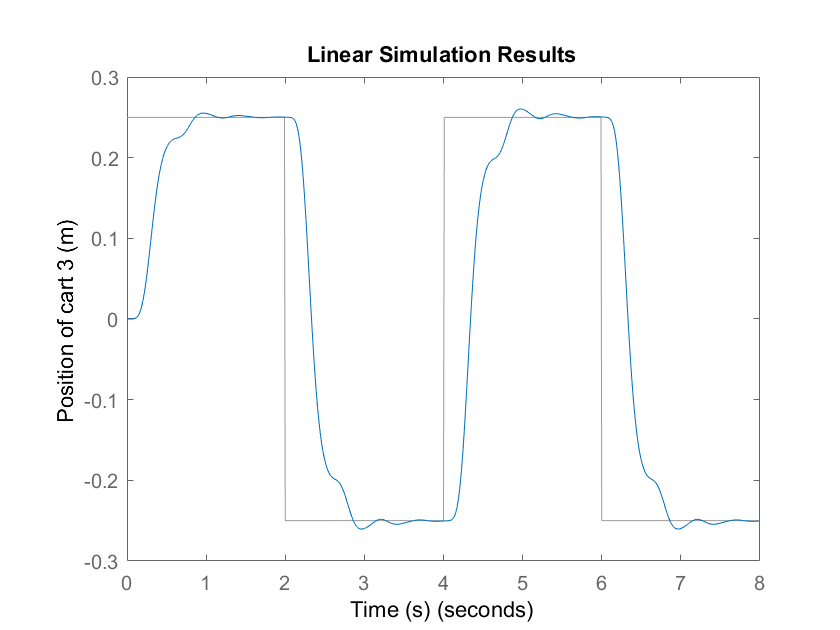


lsim(sys, rArray, tArray)

xlabel('Time (s)')
ylabel('Position of cart 3 (m)')

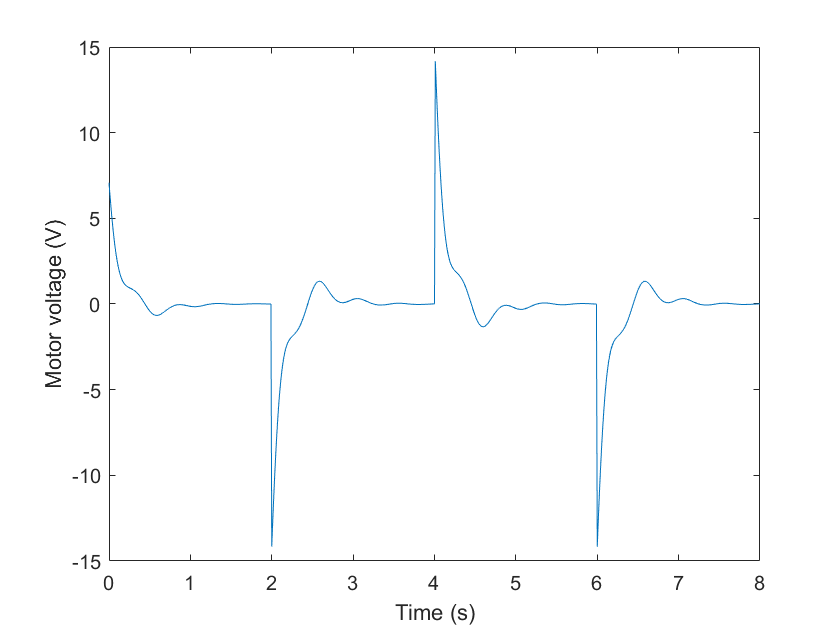


% Voltage
[y, t, x] = lsim(sys, rArray, tArray);
u = -K * x' + N * rArray;

figure
plot(t, u)

xlabel('Time (s)')
ylabel('Motor voltage (V)')

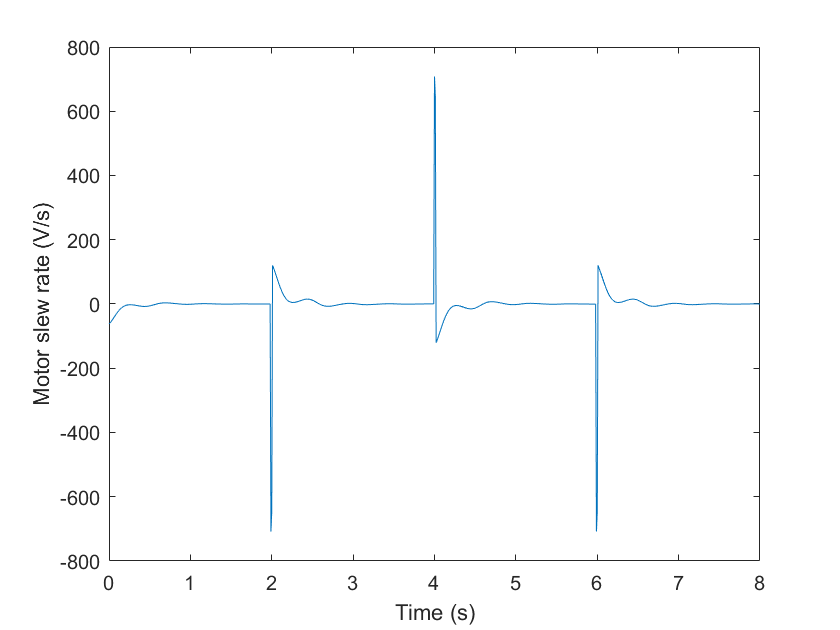


% Slew rate
dudt = gradient(u(:)) ./ gradient(t(:));

figure
plot(t, dudt)

xlabel('Time (s)')
ylabel('Motor slew rate (V/s)')